## Workshop 3

The aim of this workshop is to produce an integrated navigation solution from a combination of different technologies. Using Matlab, you will work with odometry, magnetic compass, inertial navigation and GNSS, applying Kalman filtering to integrating data from different sensors.

run 'Define_Constants.m';

### Task 1: Car Dead Reckoning

The file Workshop3_Speed_Heading.csv contains 175s of car odometry and magnetic compass data. Column 1 of this comma-separated variable (CSV) format file contains time in seconds, column 2 contains the forward speed in metres per second and column 3 contains heading in degrees. The compass provides a measurement of the instantaneous heading. However, the odometer counts wheel rotations from which it calculates the distance travelled. The odometer speed output is therefore the average speed since the previous speed measurement, not the instantaneous speed.

% Import data
speed_headings_data = readmatrix("Workshop3_Speed_heading.csv");

t_data = speed_headings_data(:,1) % Isolate time in seconds

t_data =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
    4.0000
    4.5000


v_speed_data = speed_headings_data(:,2) % Isolate average speed since previous speed measurement 

v_speed_data =    10.2200
   10.2200
   10.2200
   10.1600
   10.2000
   10.2000
   10.1800
   10.2000
   10.1400
   10.1800


psi_pb_data = speed_headings_data(:, 3) * deg_to_rad; % Isolate heading data in radians
num_epochs = length(t_data);

The initial geodetic latitude and longitude (at time 0) are ${50\ldotp 4249580}^{\circ }$ and ${-3\ldotp 5957974}^{\circ }$, respectively. 

% Initialize latitude and longitude and convert to radians
L_b = 50.4249580 * deg_to_rad;
lambda_b = -3.5957974 * deg_to_rad;

Use the speed and heading measurements to compute a position solution for the rest of the car’s trajectory.

The average velocity between epochs k−1 and k is given by

where $\overline{v}_k$ is the average speed, measured by the odometer in this case, and $\psi$ is heading, measured by the magnetic compass. Don’t forget to convert the heading from degrees to radians before inputting it to the sine and cosine functions. The constant deg_to_rad is included in the Matlab script Define_constants.m

% Average velocity between epochs
v_k_all = zeros(num_epochs - 1, 2); % Initialize average velocity between epochs (epochs - 1) by velocity values
v_k = zeros(2,1); % Initialize average velocity per epoch

% Fill in values vetween each epoch
for i = 2:num_epochs
    % Isolate input variables
    psi_k = psi_pb_data(i);
    psi_k_min_1 = psi_pb_data(i-1);
    v_Nk_temp = cos(psi_k) + cos(psi_k_min_1);
    v_Ek_temp = sin(psi_k) + sin(psi_k_min_1);

    % Note that speed already is the average between i=t and t-1
    v_k_speed = v_speed_data(i);
    
    % Calculate average velocities between epoch i=t and t-1
    v_k = 1/2 * [v_Nk_temp; v_Ek_temp] * v_k_speed;
    
    % Include in cumulative matrix
    v_k_all(i, :) = v_k';

end


The latitude, $L_k$, and longitude, $\lambda_k$, (both in radians) at epoch k can then be computed from their counterparts at epoch k-1 using.

where $t_k$ is the time at epoch k, h is the geodetic height, which you may assume remains at 37.4m throughout, RN is the meridian radius of curvature and RE is the transverse radius of curvature. The radii of curvature may be computed from the latitude using the Matlab function Radii_of_curvature. 

% Initialize 
L_k_all = zeros(num_epochs, 1);
lambda_k_all = zeros(num_epochs, 1);

% First position
L_k_min_1 = L_b

L_k_min_1 = 0.8801

lambda_k_min_1 = lambda_b

lambda_k_min_1 = -0.0628

h_b = 37.4 %m

h_b = 37.4000



% Calculate position at each epoch
for i = 2:num_epochs
    
    v_Nk = v_k_all(i-1, 1); % Corresponds to the velocity between t=i and t-1
    v_Ek = v_k_all(i-1, 2);
    t_k = t_data(i);
    t_k_min_1 = t_data(i-1);

    % Get radii
    [R_N, R_E] = Radii_of_curvature(L_k_min_1);

    % Implement formulas above
    L_k = L_k_min_1 + v_Nk * (t_k - t_k_min_1) / (R_N + h_b);
    lambda_k = lambda_k_min_1 + v_Ek * (t_k - t_k_min_1) / ((R_E + h_b) * cos(L_k));

    % Add to overall matrices
    L_k_all(i) = L_k;
    lambda_k_all(i) = lambda_k;

    % For next loop
    L_k_min_1 = L_k;
    lambda_k_min_1 = lambda_k;

end

% Initialize solutions matrix
T1_solutions = zeros(num_epochs, 5);

T1_solutions(:, 1) = t_data; % time
T1_solutions(:, 2) = L_k_all * rad_to_deg; % Latitude in degrees
T1_solutions(:, 3) = lambda_k_all * rad_to_deg; % Longitude in degrees
% Include first solution
T1_solutions(1, 2) = L_k_min_1 *rad_to_deg;
T1_solutions(1, 3) = lambda_k_min_1 *rad_to_deg;

To prepare for task 2, compute the damped instantaneous DR velocity at each epoch using

You may assume that the instantaneous velocity at time zero is given by the speed and heading measurements at that time. Thus $v_{N,0} = v_0 \cos\psi_0$ and $v_{E,0} = v_0 \sin \psi_0$ without damping, the instantaneous velocity would be $2\overline{v}_k-v_{k-1}$. However, unless the sensors are perfect, an oscillating error results. Therefore, damping is used to prevent the error build-up at the expense of introducing a time lag.

v_k_all_dampened = zeros(size(v_k_all));

% Calculate velocity at first epoch
v_Nk_min_1 = v_speed_data(1) * cos(psi_pb_data(1));
v_Ek_min_1 = v_speed_data(1) * sin(psi_pb_data(1));

v_k_all_dampened(1,:) = [v_Nk_min_1, v_Ek_min_1];

for i = 2:num_epochs
    v_Nk = v_k_all(i, 1);
    v_Ek = v_k_all(i, 2);

    v_Nk_dampened = 1.7 * v_Nk - 0.7 * v_Nk_min_1;
    v_Ek_dampened = 1.7 * v_Ek - 0.7 * v_Ek_min_1;

    v_k_all_dampened(i,:) = [v_Nk_dampened, v_Ek_dampened];

    % For next loop
    v_Nk_min_1 = v_Nk_dampened; % Note that you use the dampened values for future iterations
    v_Ek_min_1 = v_Ek_dampened;
end

T1_solutions(:, 4:5) = v_k_all_dampened;

### Task 2 Car DR/GNSS Integration

The file Workshop3_GNSS_Pos_Vel.csv contains the GNSS position and velocity solution for the same car as in Task 1. The format is as follows:

- Column 1 contains time in seconds

- Column 2 contains geodetic latitude in degrees

- Column 3 contains geodetic longitude in degrees

- Column 4 contains geodetic height in metres

- Columns 5 to 7 contain Earth-referenced velocity in metres per second, resolved along north, east and down, respectively.

% Import data
GNSS_pos_vel_data = readmatrix("Workshop3_GNSS_Pos_Vel_NED.csv");

% Isolate columns
t_data = GNSS_pos_vel_data(:,1); % seconds
L_k_data = GNSS_pos_vel_data(:, 2) * deg_to_rad; % radians
lambda_k_data = GNSS_pos_vel_data(:, 3) * deg_to_rad; % radians
h_k_data = GNSS_pos_vel_data(:, 4); % metres
v_k_data = GNSS_pos_vel_data(:, 5:7); % metres/s
num_epochs = length(GNSS_pos_vel_data);

% Isolate dead reckoning solution
L_k_DR_all = T1_solutions(:, 2) * deg_to_rad;
lambda_k_DR_all = T1_solutions(:, 3) * deg_to_rad;
v_Nk_DR_all = T1_solutions(:, 4);
v_Ek_DR_all = T1_solutions(:, 5);

% Corrected DR estimates
corrected_DR_solutions = zeros(size(T1_solutions));

Your task is to compute an integrated horizontal-only DR/GNSS navigation solution using Kalman filtering. You will implement a 4-state Kalman filter estimating north and east DR velocity error, DR latitude error and DR longitude error. The state vector is thus

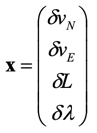

Initially, you don’t know what the DR errors are, so initialise all 4 states at zero. 

x_k_min_1_est = zeros(4, 1); % Initialize as zero's vector

Assume that your initial velocity uncertainty is, $\sigma_v$ = 0.1 m/s in each direction and that your initial position uncertainty is $\sigma_r$ = 10m per direction. The state estimation error covariance matrix is therefore initialised at

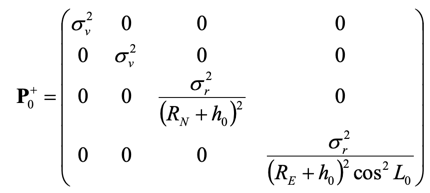

You can use the GNSS latitude and height from Workshop3_GNSS_Pos_Vel.csv at time 0.

% Initialize uncertainties
sigma_v = 0.1; %m/s
sigma_r = 10; %m

% Calculate radii and isolate initial position
L_k =  L_k_data(1); % degrees
lambda_k = lambda_k_data(1); % degrees
h_k = h_k_data(1); % metres
[R_N, R_E] = Radii_of_curvature(L_k);

% Setup state estimation error covariance matrix
diag_values = [sigma_v^2, sigma_v^2, sigma_r^2 / (R_N + h_k)^2, sigma_r^2 / (R_E + h_k)^2 * cos(L_k)^2];

P_k_min_1_est = diag(diag_values);

Then follow the ten steps of the Kalman filter as follows:

% Given values
tau_s = 0.5; %seconds 
S_DR = 0.2; %m^2 s^-3
sigma_Gr = 5; %m
sigma_Gv = 0.02; % m/s

% For each epoch, follow all of the steps

for i = 2:num_epochs

    % Get inputs
    % k-1 inputs
    h_k_min_1 = h_k_data(i-1);
    L_k_min_1 = L_k_data(i-1);
    [R_N_k_min_1, R_E_k_min_1] = Radii_of_curvature(L_k_min_1);

    % k inputs
    h_k = h_k_data(i);
    L_k = L_k_data(i);
    lambda_k = lambda_k_data(i);
    v_Nk = v_k_data(i, 1);
    v_Ek = v_k_data(i, 2);
    [R_N_k, R_E_k] = Radii_of_curvature(L_k);

    % Input components of DR solution
    L_k_DR = L_k_DR_all(i);
    lambda_k_DR = lambda_k_DR_all(i);
    v_Nk_DR = v_Nk_DR_all(i);
    v_Ek_DR = v_Ek_DR_all(i);

    % Step 1: Compute transition matrix 
    Phi_k_min_1 = eye(4);
    Phi_k_min_1(3, 1) = tau_s / (R_N_k_min_1 + h_k_min_1);
    Phi_k_min_1(4, 2) = tau_s / ((R_E_k_min_1 + h_k_min_1) * cos(L_k_min_1));

    % Step 2: Compute the system noise covariance matrix
    % Cleaner way to do this?
    Q_k_min_1 = zeros(4, 4);
    Q_k_min_1(1, 1) = S_DR * tau_s;
    Q_k_min_1(2, 2) = S_DR * tau_s;
    Q_k_min_1(3, 1) = 1/2 * (S_DR * tau_s^2) / (R_N_k_min_1 + h_k_min_1);
    Q_k_min_1(4, 2) = 1/2 * (S_DR * tau_s^2) / ((R_E_k_min_1 + h_k_min_1) * cos(L_k_min_1));
    Q_k_min_1(1, 3) = 1/2 * (S_DR * tau_s^2) / (R_N_k_min_1 + h_k_min_1);
    Q_k_min_1(3, 3) = 1/3 * (S_DR * tau_s^3) / (R_N_k_min_1 + h_k_min_1)^2;
    Q_k_min_1(2, 4) = 1/2 * (S_DR * tau_s^2) / ((R_E_k_min_1 + h_k_min_1) * cos(L_k_min_1));
    Q_k_min_1(4, 4) = 1/3 * (S_DR * tau_s^3) / ((R_E_k_min_1 + h_k_min_1)^2 * cos(L_k_min_1)^2);

    % Step 3: Propogate the state estimates
    x_k_pred = Phi_k_min_1 * x_k_min_1_est;

    % Step 4: Propogate the error covariance matrix
    P_k_pred = Phi_k_min_1 * P_k_min_1_est * Phi_k_min_1' + Q_k_min_1;

    % Step 5: Compute the measurement matrix
    H_k = zeros(4,4);
    H_k(1, 3) = -1;
    H_k(2, 4) = -1;
    H_k(3, 1) = -1;
    H_k(4, 2) = -1;

    % Step 6: Compute the measurement noise covariance matrix
    diag_values = [sigma_Gr^2 / (R_N_k + h_k)^2, sigma_Gr^2 / ((R_E_k + h_k)^2 * cos(L_k)^2), ...
        sigma_Gv^2, sigma_Gv^2];

    R_k = diag(diag_values);

    % Step 7: Compute the Kalman gain matrix
    K_k = P_k_pred * H_k' * inv(H_k * P_k_pred * H_k' + R_k);

    % Step 8: Formulate the measurement innovation vector 
    % L_k is L_k_G and so forth
    % Note order of the state vector x
    partial_z_k_pred = [L_k - L_k_DR + x_k_pred(3); ...
        lambda_k - lambda_k_DR + x_k_pred(4); ...
        v_Nk - v_Nk_DR + x_k_pred(1); ...
        v_Ek - v_Ek_DR + x_k_pred(2)];

    % Step 9: Update the state estimates
    x_k_est = x_k_pred + K_k * partial_z_k_pred;

    % Step 10: Update the error covariance matrix
    P_k_est = (eye(4) - K_k * H_k) * P_k_pred;

    % Correct DR estimates
    corrected_DR_solutions(i, 2) = L_k_DR - x_k_est(3);
    corrected_DR_solutions(i, 3) = lambda_k_DR - x_k_est(4);
    corrected_DR_solutions(i, 4) = v_Nk_DR - x_k_est(1);
    corrected_DR_solutions(i, 5) = v_Ek_DR - x_k_est(2);

    % For next epoch
    x_k_pred = x_k_est;
    P_k_pred = P_k_est;

end

corrected_DR_solutions(:, 2) = corrected_DR_solutions(:, 2) * rad_to_deg;
corrected_DR_solutions(:, 3) = corrected_DR_solutions(:, 3) * rad_to_deg;
% Include first solution
corrected_DR_solutions(1, 2) = L_k_data(1) * rad_to_deg;
corrected_DR_solutions(1, 3) = lambda_k_data(1) * rad_to_deg;
corrected_DR_solutions(1, 4) = v_k_data(1, 1);
corrected_DR_solutions(1, 5) = v_k_data(1, 2);

### Task 3: UAV INS/GNSS Integration (OPTIONAL)

Workshop 2 concerned an unmanned air vehicle (UAV) is flying over the Amazon jungle in Brazil, conducting an aerial survey to detect unauthorised logging. As well as GNSS data, the UAV’s inertial navigation solution is also logged every second. Your task is to comput an integrated INS/GNSS navigation solution using Kalman filtering.

Use your GNSS position and velocity solution from Workshop 2 Task 2 to correct and calibrate the inertial navigation solution. Make sure that you saved your GNSS position and velocity solution with sufficient precision. Your latitude and longitude should have a precision of at least 10−7 degrees, your height 1 mm and your velocity 1 mm/s.

The inertial navigation solution is supplied in the file Aircraft_inertial.csv, which is in comma-separated variable (CSV) format. This contains latitude, $L_b$ (degrees), longitude, $\lambda_b$ (degrees), height, $h_b$ (m), north, east, down velocity, $v^n_{eb}$ (m/s), Euler attitude, $\psi_{nb}$ (degrees), and $\textbf{f}^b_{ib}$ specific force, (m/s2).

The file Aircraft_inertial.csv is organised as follows:

- Column 1 contains time in seconds

- Column 2 contains geodetic latitude in degrees

- Column 3 contains geodetic longitude in degrees

- Column 4 contains geodetic height in metres

- Columns 5 to 7 contain Earth-referenced velocity in metres per second, resolved along north, east and down, respectively.

- Columns 8 to 10 contain, respectively, roll, pitch and heading, all in degrees.

- Columns 11 to 13 contain the measured specific force, resolved along the body-frame axes in metres per second squared.

% Import data and convert all degrees to radians
aircraft_inertial_data = readmatrix("Aircraft_inertial.csv");
L_k_data = aircraft_inertial_data(:, 2) * deg_to_rad; % rad
lambda_k_data = aircraft_inertial_data(:, 3) * deg_to_rad; % rad
h_k_data = aircraft_inertial_data(:, 4); %m
v_k_data = aircraft_inertial_data(:, 5:7); %m/s
psi_k_data = aircraft_inertial_data(:, 8:10) * deg_to_rad; % rad
f_k_data = aircraft_inertial_data(:, 11:13); %m/s^2
num_epochs = length(aircraft_inertial_data);

% Initialize x and P
[x_k_min_1_est, P_k_min_1_est] = Initialise_Integration_KF;

% Given values 
tau_s = 1; % second
S_rg = LC_KF_config.gyro_noise_PSD;
S_ra = LC_KF_config.accel_noise_PSD;
S_bad = LC_KF_config.accel_bias_PSD;
S_bgd = LC_KF_config.gyro_bias_PSD;

% Used in loops
I_3 = eye(3);


% for each epoch
for i = 2:num_epochs

    % Step 1: Compute transition matrix
    C_n_b = Euler_to_CTM(psi_k_data(i-1, :)'); % First underscore is subscript, second superscript
    C_b_n = C_n_b';
    [r_eb_e, v_eb_e, C_b_e] = NED_to_ECEF(L_k_data(i-1) ,lambda_k_data(i-1),h_k_data(i-1) ,v_k_data(i-1, :)', C_b_n); % ECEF
    F21 = Calculate_F21(C_b_e, f_k_data(i-1, :)');
    F23 = Calculate_F23(r_eb_e, L_k_data(i-1));

    Phi_k_min_1 = eye(15);
    Phi_k_min_1(1:3, 1:3) = I_3 - Omega_ie * tau_s;
    Phi_k_min_1(4:6, 1:3) = F21 * tau_s;
    Phi_k_min_1(4:6, 4:6) = I_3 - 2 * Omega_ie * tau_s;
    Phi_k_min_1(7:9, 4:6) = I_3 * tau_s;
    Phi_k_min_1(4:6, 7:9) = F23 * tau_s;
    Phi_k_min_1(4:6, 10:12) = C_b_e * tau_s;
    Phi_k_min_1(1:3, 13:15)= C_b_e * tau_s;
    
    % Step 2: Compute the system noise covariance matrix
    Q_k_min_1 = eye(15)
    


    % Step 3: Propogate the state estimates


    % Step 4: Propogate the error covariance matrix


    % Step 5: Compute the measurement matrix


    % Step 6: Compute the measurement noise covariance matrix


    % Step 7: Compute the Kalman gain matrix


    % Step 8: Formulate the measurement innovation vector 


    % Step 9: Update the state estimates


    % Step 10: Update the error covariance matrix


    % For next epoch

end

